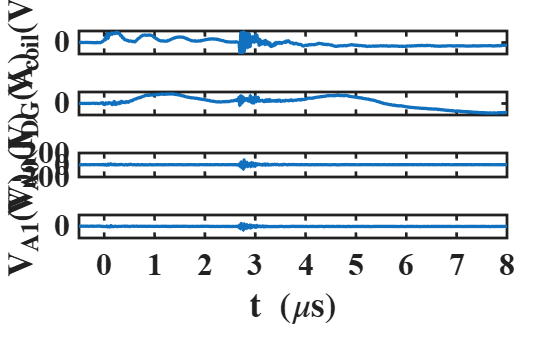

clear; clc; close all;

% =========================================================
% File Configuration
% =========================================================
before_noPinch = 'DAY 3-13-2025\Ex03\DataLog_0008_Analog.csv';
after_noPinch  = 'DAY 4-9-2025\Ex02\DataLog_0000_Analog.csv';
before_Pinch   = 'DAY 3-17-2025\Ex09\DataLog_0000_Analog.csv';
after_Pinch    = 'DAY 4-8-2025\Ex22\DataLog_0000_Analog.csv';

Folder_dir = fullfile(fileparts(matlab.desktop.editor.getActiveFilename), 'ExperimentData');

path = after_Pinch;
scope1 = fullfile(Folder_dir, path);

% =========================================================
% Plot Configuration
% =========================================================
GLOBAL_FS = 24;
GLOBAL_FN = 'Times New Roman';
GLOBAL_FW = 'bold';

LW = 2.5;

CH1_LIM = [-5 5];
CH2_LIM = [-5 5];
CH3_LIM = [-200 200];
CH4_LIM = [-200 200];

CH = [-0.5 8];

My_XTicks = 0:1:8;
FFT_ylim = [0 3];

apply_ax_styles = @(ax) set(ax, ...
    'FontSize', GLOBAL_FS, ...
    'FontName', GLOBAL_FN, ...
    'FontWeight', GLOBAL_FW, ...
    'LineWidth', 2.0);

% =========================================================
% Data Acquisition
% =========================================================
try
    data = readtable(scope1);

    time = table2array(data(17:125016, 1));
    time = (time - time(1)) - 2E-6;

    CH1 = table2array(data(17:125016, 2));
    CH2 = table2array(data(17:125016, 3));
    CH3 = table2array(data(17:125016, 4));
    CH4 = table2array(data(17:125016, 5));

catch
    disp('CSV file not found. Generating simulated data.');

    time = linspace(0, 10E-6, 100000)';

    CH1 = 2*sin(2*pi*1E6*time) + 0.5*randn(size(time));
    CH2 = 1.5*cos(2*pi*1E6*time) + 0.2*randn(size(time));
    CH3 = 100*sin(2*pi*1E6*time) + 10*randn(size(time));
    CH4 = 120*cos(2*pi*1E6*time) + 15*randn(size(time));
end

% =========================================================
% Time-Domain Analysis
% =========================================================
figure('Name', 'Time Domain Signals', 'Color', 'w');
tiledlayout(4, 1, 'TileSpacing', 'tight');

y_labels = gobjects(4, 1);

nexttile;
plot(time*1E6, CH1, 'LineWidth', LW);

y_labels(1) = ylabel( ...
    '$\textit{\textbf{V}}_{\textbf{coil}}\textbf{(V)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

xticks(My_XTicks);
xticklabels([]);
ylim(CH1_LIM);
xlim(CH);

apply_ax_styles(gca);

nexttile;
plot(time*1E6, CH2, 'LineWidth', LW);

y_labels(2) = ylabel( ...
    '$\textit{\textbf{I}}_{\textbf{DG}}\textbf{(A)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

xticks(My_XTicks);
xticklabels([]);
ylim(CH2_LIM);
xlim(CH);

apply_ax_styles(gca);

nexttile;
plot(time*1E6, CH3, 'LineWidth', LW);

y_labels(3) = ylabel( ...
    '$\textit{\textbf{V}}_{\textbf{A0}}\textbf{(V)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

xticks(My_XTicks);
xticklabels([]);
ylim(CH3_LIM);
xlim(CH);

apply_ax_styles(gca);

nexttile;
plot(time*1E6, CH4, 'LineWidth', LW);

y_labels(4) = ylabel( ...
    '$\textit{\textbf{V}}_{\textbf{A1}}\textbf{(V)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

xlabel( ...
    '$\textit{\textbf{t}}\ \textbf{(}\mu\textbf{s)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

xticks(My_XTicks);
ylim(CH4_LIM);
xlim(CH);

apply_ax_styles(gca);

% Align Y-axis labels across all subplots.
set(y_labels, 'Units', 'normalized');
set(y_labels, 'Position', [-0.08, 0.5, 0]);

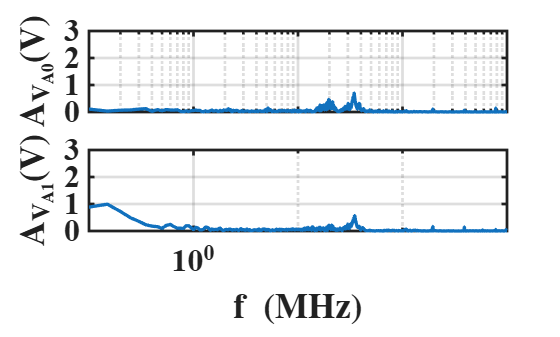


% =========================================================
% FFT Calculation
% =========================================================
dt = mean(diff(time));
Fs = 1/dt;

% CH3: VA0
N3 = length(CH3);

Y3 = fft(CH3);
P2_3 = abs(Y3/N3);

P1_3 = P2_3(1:floor(N3/2)+1);
P1_3(2:end-1) = 2*P1_3(2:end-1);

f3 = Fs*(0:floor(N3/2))/N3;

% CH4: VA1
N4 = length(CH4);

Y4 = fft(CH4);
P2_4 = abs(Y4/N4);

P1_4 = P2_4(1:floor(N4/2)+1);
P1_4(2:end-1) = 2*P1_4(2:end-1);

f4 = Fs*(0:floor(N4/2))/N4;

% =========================================================
% Frequency-Domain Analysis
% =========================================================
figure('Name', 'FFT Analysis', 'Color', 'w');
tiledlayout(2, 1, 'TileSpacing', 'tight');

nexttile;
semilogx(f3/1E6, P1_3, 'LineWidth', LW);

xticklabels([]);

ylabel( ...
    '$\textit{\textbf{A}}_{\textit{\textbf{V}}_{\textbf{A0}}}\textbf{(V)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

xlim([1E-1 1E3]);
ylim(FFT_ylim);

grid on;
apply_ax_styles(gca);

nexttile;
semilogx(f4/1E6, P1_4, 'LineWidth', LW);

xlabel( ...
    '$\textit{\textbf{f}}\ \textbf{(MHz)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

ylabel( ...
    '$\textit{\textbf{A}}_{\textit{\textbf{V}}_{\textbf{A1}}}\textbf{(V)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

xlim([1E-1 1E3]);
ylim(FFT_ylim);

grid on;
apply_ax_styles(gca);

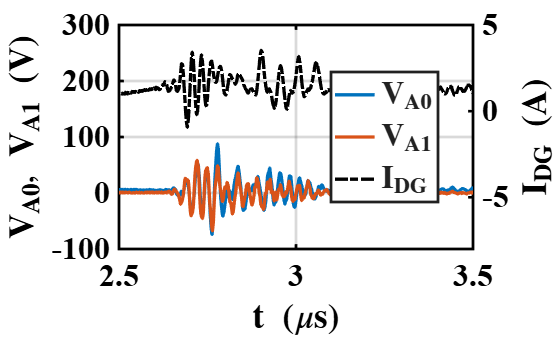


% =========================================================
% Overlay Analysis: VA0, VA1, and IDG
% =========================================================
figure('Name', 'Overlay VA0 VA1 and IDG', 'Color', 'w');

ax = gca;

% Left Y-axis: VA0 and VA1
yyaxis left;

p1 = plot(time*1E6, CH3, ...
    'LineWidth', LW, ...
    'Color', [0 0.4470 0.7410], ...
    'LineStyle', '-', ...
    'DisplayName', '$\textit{\textbf{V}}_{\textbf{A0}}$');

hold on;

p2 = plot(time*1E6, CH4, ...
    'LineWidth', LW, ...
    'Color', [0.8500 0.3250 0.0980], ...
    'LineStyle', '-', ...
    'DisplayName', '$\textit{\textbf{V}}_{\textbf{A1}}$');

ylabel( ...
    '$\textit{\textbf{V}}_{\textbf{A0}},\ \textit{\textbf{V}}_{\textbf{A1}}\ \textbf{(V)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

ylim([-100 300]);

% Right Y-axis: IDG
yyaxis right;

p3 = plot(time*1E6, CH2, ...
    'LineWidth', LW, ...
    'Color', [0 0 0], ...
    'LineStyle', '-.', ...
    'DisplayName', '$\textit{\textbf{I}}_{\textbf{DG}}$');

ylabel( ...
    '$\textit{\textbf{I}}_{\textbf{DG}}\ \textbf{(A)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

ylim([-8 5]);

% Common X-axis
xlabel( ...
    '$\textit{\textbf{t}}\ \textbf{(}\mu\textbf{s)}$', ...
    'Interpreter', 'latex', 'FontSize', GLOBAL_FS);

xlim([2.5 3.5]);

grid on;
box on;

apply_ax_styles(ax);

ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';
ax.XAxis.Color = 'k';

% Legend
lgd = legend([p1 p2 p3], ...
    'Interpreter', 'latex', ...
    'Location', 'best');

set(lgd, ...
    'FontSize', GLOBAL_FS, ...
    'FontName', GLOBAL_FN, ...
    'FontWeight', GLOBAL_FW);